EbNodB = 0:0.5:10;

baseGraph5GNR = 'NR_2_6_52'; % load 5G NR LDPC base H matrix, use both NR_2_6_52 and NR_1_5_352
R = [1/4, 1/3, 1/2, 3/5];
%R=1/4;
% vary this in the set {1/4, 1/3, 1/2, 3/5} for 2_6_52 and in the range {1/3, 1/2, 3/5 and 4/5} for 1_5_352
[B,Hfull,z] = nrldpc_Hmatrix(baseGraph5GNR); % Convert the base H matrix to binary H matrix
[mb,nb] = size(B); kb = nb - mb; % 5G NR specific details
BER = zeros(length(R), length(EbNodB));
error_prob = zeros(length(R), length(EbNodB));
itmax=15;     
%success_iteration = zeros(length(EbNodB), itmax);
index = 1;

for codeRate = R 

    kNumInfoBits = kb * z; % Number of information bits
    k_pc = kb-2; nbRM = ceil(k_pc/codeRate)+2; % Some 5G NR specific details 
    nBlockLength = nbRM * z; % Number of encoded bits
    
    % Next three lines are some 5G NR specific details
    H = Hfull(:,1:nBlockLength); 
    nChecksNotPunctured = mb*z - nb*z + nBlockLength;
    H = H(1:nChecksNotPunctured,:); % this is the binary H matrix
    
    Nchecks = size(H,1); % Number of CNs (we have denoted this as U = N - K in the class)
    n=length(H(1,:));%Number of VNs
    u=length(H(:,1));%Number of CNs
    k=n-u;%Number of message bits

    %Creating adjacency list for VN
    adj_VN=cell(1,n);
    for l=1:n
        temp=[];
            for m=1:u
                if(H(m,l)==1)
                temp(end+1)=m;
                end
            end
        adj_VN{l} = temp;
    end

    %Creating adjacency list for CN
    adj_CN=cell(1,u);
    for l=1:u
        temp=[];
            for m=1:n
                if(H(l,m)==1)
                temp(end+1)=m;
                end
           end
        adj_CN{l} = temp;
    end
    
    err_index = 1;
    %Loop for all the EbNo
    for jEb=EbNodB
        jEb
        EbNo = 10^(jEb/10);
        sigma = sqrt (1/ (2*codeRate*EbNo));
        %sigma=0;
        BER_th = 0.5.*erfc(sqrt(EbNo) );
        Nerrs = 0;

        %Number of simulations
        N=2;
        
        error=0;
            for Nsim = 1 : N %Loop for Number of Simulation
                b = randi([0 1],[kNumInfoBits 1]); % Generate information (or message) bit vector
                encoded_message = nrldpc_encode(B,z,b'); % Encode using 5G NR LDPC base matrix 
                encoded_message = encoded_message(1:nBlockLength)';

                tc= randn(nBlockLength,1);

                s = 1 - 2 * encoded_message; %BPSK bit to symbol conversion modulation
                r = s + sigma * tc; %AWGN channel

               msg_cap = (r < 0); %threshold at zero
               c_received=msg_cap';
               VN=c_received;
               prev_msg=msg_cap';
               it=1;


           while(it<=itmax)%While loop for iterations

           if(it==1)
          
            
           %This adjacency list will store message sent By CN to VN
           msg_CN_2_VN = cell(1, n);

           for i=1:u % Loop for traversing each CN 
               sumxor=0;
               for j=1:size(adj_CN{i},2) %Loop for traversing each VN connected to CN
                    sumxor=mod(sumxor+VN(1,adj_CN{i}(j)),2);
               end

               for j=1:size(adj_CN{i},2) %Loop for traversing each VN connected to CN
                     tempxor = mod(sumxor + VN(1,adj_CN{i}(j)), 2);
                     msg_CN_2_VN{adj_CN{i}(j)}(end + 1) = tempxor;
               end
           end     
           else

               %This adjacency list will store message sent By VN to CN
               msg_VN_2_CN=cell(1,u);

               for i=1:n % Loop for traversing each VN
                  cnt=c_received(1,i);
                    
                   for j=1:size(adj_VN{i},2)  %Loop for traversing each CN connected to VN
                        cnt=cnt+msg_CN_2_VN{i}(j);
                   end

                   for j=1:size(adj_VN{i},2)  %Loop for traversing each CN connected to VN
                        tempcnt=cnt-msg_CN_2_VN{i}(j);

                        if(tempcnt>((size(adj_VN{i},2))/2))
                           msg_VN_2_CN{adj_VN{i}(j)}(end+1)=1;
                        else
                            msg_VN_2_CN{adj_VN{i}(j)}(end+1)=0;
                        end
                   end

               end


               tempVN=zeros(1,n);
               for i=1:n %Loop for traversing each VN
                   
                    cnt1 = c_received(1,i);

                    for j=1:size(adj_VN{i},2)  %Loop for traversing each CN connected to VN
                         cnt1 = cnt1 + msg_CN_2_VN{i}(j);
                    end

                    if(cnt1 > (size(adj_VN{i},2)+1)/2)
                        tempVN(1,i)=1;
                    end

               end
                
                
              
                  VN=tempVN;   %Updating each VN
                  msg_CN_2_VN = cell(1, n);

               for i=1:u % Loop for traversing each CN 
               sumxor=0;

                    for j=1:size(adj_CN{i},2) %Loop for traversing each VN connected to CN
                        sumxor=mod(sumxor+msg_VN_2_CN{i}(j),2);
                    end
       
                    for j=1:size(adj_CN{i},2) %Loop for traversing each VN connected to CN
                        tempxor = mod(sumxor + msg_VN_2_CN{i}(j), 2);
                        msg_CN_2_VN{adj_CN{i}(j)}(end + 1) = tempxor;
                    end

                end
      
           end

                   decoded_message = VN; 
                   it=it+1;
           end
            biterror = sum(xor(decoded_message, encoded_message'));
            if(biterror > 0)
                BER(index, err_index) = BER(index, err_index) + biterror;
                error_prob(index, err_index) = error_prob(index, err_index) + 1;
            end

       
            end
            BER(index, err_index) = BER(index, err_index) / n / N;
            error_prob(index, err_index) = error_prob(index, err_index) / N;
            err_index = err_index + 1;

end

index = index + 1;


end

jEb = 0

jEb = 0.5000

jEb = 1

jEb = 1.5000

jEb = 2

jEb = 2.5000

jEb = 3

jEb = 3.5000

jEb = 4

jEb = 4.5000

jEb = 5

jEb = 5.5000

jEb = 6

jEb = 6.5000

jEb = 7

jEb = 7.5000

jEb = 8

jEb = 8.5000

jEb = 9

jEb = 9.5000

jEb = 10

jEb = 0

jEb = 0.5000

jEb = 1

jEb = 1.5000

jEb = 2

jEb = 2.5000

jEb = 3

jEb = 3.5000

jEb = 4

jEb = 4.5000

jEb = 5

jEb = 5.5000

jEb = 6

jEb = 6.5000

jEb = 7

jEb = 7.5000

jEb = 8

jEb = 8.5000

jEb = 9

jEb = 9.5000

jEb = 10

jEb = 0

jEb = 0.5000

jEb = 1

jEb = 1.5000

jEb = 2

jEb = 2.5000

jEb = 3

jEb = 3.5000

jEb = 4

jEb = 4.5000

jEb = 5

jEb = 5.5000

jEb = 6

jEb = 6.5000

jEb = 7

jEb = 7.5000

jEb = 8

jEb = 8.5000

jEb = 9

jEb = 9.5000

jEb = 10

jEb = 0

jEb = 0.5000

jEb = 1

jEb = 1.5000

jEb = 2

jEb = 2.5000

jEb = 3

jEb = 3.5000

jEb = 4

jEb = 4.5000

jEb = 5

jEb = 5.5000

jEb = 6

jEb = 6.5000

jEb = 7

jEb = 7.5000

jEb = 8

jEb = 8.5000

jEb = 9

jEb = 9.5000

jEb = 10

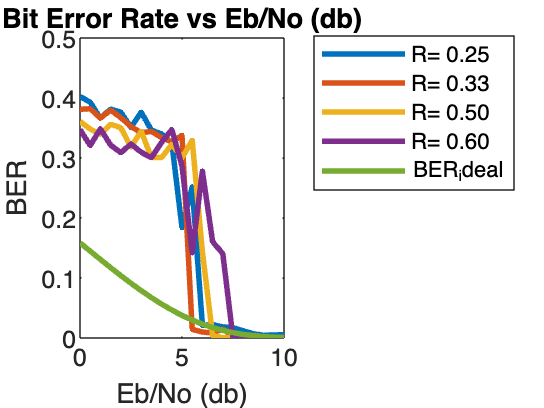


% Now convertting SNR ratio to linear scale
Ebnolinear=10.^(EbNodB./10);
BER_ideal = 0.5*erfc(sqrt(Ebnolinear./2));



for i = 1:1:4
    plot(EbNodB, BER(i, :), 'DisplayName',sprintf('R= %.2f', R(i)), LineWidth=2);
    hold on;
end
plot(EbNodB,BER_ideal,'DisplayName','BerIdeal',lineWidth=2)
legend('show','Location','bestoutside');
title('Bit Error Rate vs Eb/No (db)');
xlabel('Eb/No (db)');
ylabel('BER');
hold off;

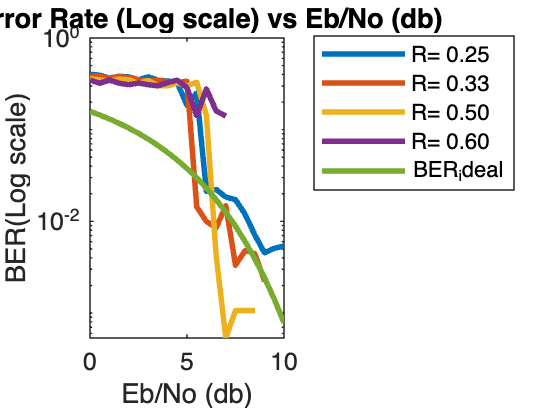



for i = 1:1:4
    semilogy(EbNodB, BER(i, :), 'DisplayName',sprintf('R= %.2f', R(i)), LineWidth=2);
    hold on;
end
semilogy(EbNodB,BER_ideal,'DisplayName','BerIdeal',lineWidth=2)
legend('show','Location','bestoutside');
title('Bit Error Rate (Log scale) vs Eb/No (db)')
xlabel('Eb/No (db)');
ylabel('BER(Log scale)');


hold off;

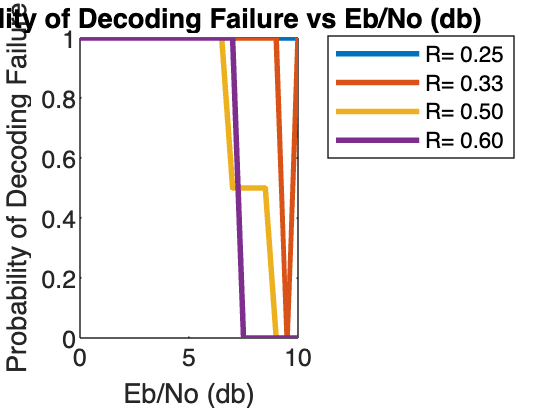


for i = 1:1:4
    plot(EbNodB, error_prob(i, :), 'DisplayName',sprintf('R= %.2f', R(i)), LineWidth=2);
    hold on;
end
legend('show','Location','bestoutside');
title('Probability of Decoding Failure vs Eb/No (db)');
xlabel('Eb/No (db)');
ylabel('Probability of Decoding Failure');


hold off;

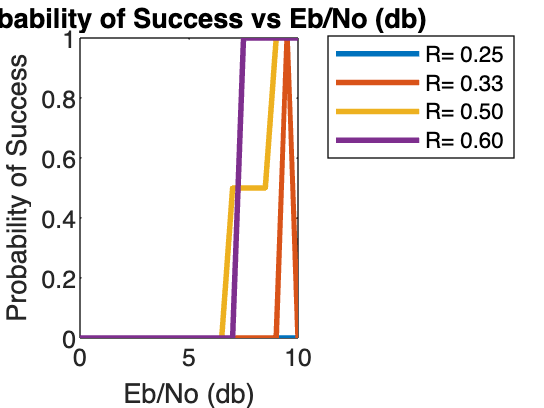



for i = 1:1:4
    plot(EbNodB, 1 - error_prob(i, :), 'DisplayName',sprintf('R= %.2f', R(i)), LineWidth=2);
    hold on;
end
legend('show','Location','bestoutside');
title('Probability of Success vs Eb/No (db)');
xlabel('Eb/No (db)');
ylabel('Probability of Success');


hold off;


%for i = 1:length(EbNodB)
% plot(1:1:itmax, success_iteration(i, :)/N, 'DisplayName',sprintf('Ebnodb = %.2f', EbNodB(i)), LineWidth=2);
% hold on;
%end
%legend('show','Location','bestoutside');
%title('Success Probability vs Iterations For R=3/5');
%xlabel('Iterations');
%ylabel('Success Probability');
%hold off;

%FUNCTIONS:

function [B,H,z] = nrldpc_Hmatrix(BG)

load(sprintf('%s.txt',BG),BG);
B = NR_2_6_52;
[mb,nb] = size(B);
z = 52;
H = zeros(mb*z,nb*z); 
Iz = eye(z); I0 = zeros(z);
for kk = 1:mb
    tmpvecR = (kk-1)*z+(1:z);
    for kk1 = 1:nb
        tmpvecC = (kk1-1)*z+(1:z);
        if B(kk,kk1) == -1
            H(tmpvecR,tmpvecC) = I0;
        else
            H(tmpvecR,tmpvecC) = circshift(Iz,-B(kk,kk1));
        end
    end
end
[U,N]=size(H); K = N-U;
P = H(:,1:K);
G = [eye(K); P];
Z = H*G;
end

function cword = nrldpc_encode(B,z,msg)
%B: base matrix
%z: expansion factor
%msg: message vector, length = (#cols(B)-#rows(B))*z
%cword: codeword vector, length = #cols(B)*z


[m,n] = size(B);


cword = zeros(1,n*z);
cword(1:(n-m)*z) = msg;


%double-diagonal encoding
temp = zeros(1,z);
for i = 1:4 %row 1 to 4
    for j = 1:n-m %message columns
        temp = mod(temp + mul_sh(msg(((j-1)*z+1):(j*z)),B(i,j)),2);
    end
end
if B(2,n-m+1) == -1
    p1_sh = B(3,n-m+1);
else
    p1_sh = B(2,n-m+1);
end


cword((n-m)*z+1:(n-m+1)*z) = mul_sh(temp,z-p1_sh); %p1
%Find p2, p3, p4
for i = 1:3
    temp = zeros(1,z);
    for j = 1:n-m+i
        temp = mod(temp + mul_sh(cword(((j-1)*z+1):(j*z)),B(i,j)),2);
    end
    cword((n-m+i)*z+1:(n-m+i+1)*z) = temp;
end


%Remaining parities
for i = 5:m
    temp = zeros(1,z);
    for j = 1:n-m+4
        temp = mod(temp + mul_sh(cword(((j-1)*z+1):(j*z)),B(i,j)),2);        
    end
    cword((n-m+i-1)*z+1:(n-m+i)*z) = temp;    
end


end

function y = mul_sh(x,k)
if (k==-1)
    y = zeros(1,length(x));
else
    y = [x(k+1:end) x(1:k)];
end
end

